# **PROJETO ATD**

## **META 1**

%MAIN.M

%

% Este script realiza as seguintes tarefas:

% 1) Cria uma tabela de metadados para os áudios e importa os sinais.

% 2) Realiza pré-processamento dos sinais (remoção de silêncio inicial,

   % normalização, sem ajuste de duração para features).

% 3) Representa graficamente os sinais brutos para dígitos 0-9, repetição 5.
% 4) Extrai 5 características temporais de cada sinal antes de padding.

% 5) Representa graficamente os sinais pré-processados para dígitos 0-9, repetição 5.

% 6) Compara visualmente os gráficos de 3 e 5 (descrito no texto).

% 7) Visualiza as features e identifica as melhores para discriminação.

% 8) Remove os sinais de áudio da tabela e salva em finalData.mat.


#### PARÂMETROS INICIAIS

clear; close all; clc;


audioFolderPath      = './data/40';   
participantID        = 40;           % Nº participante
digitNumbers         = 0:9;          % Digitos de 0 a 9
repetitionNumbers    = 0:49;         % 50 ficheiros por digito
numberOfDigits       = length(digitNumbers);
numberOfRepetitions  = length(repetitionNumbers);

#### EX 1 e 2 : Criação da estrutura de dados e importação dos sinais de áudio

totalRecordings = numberOfDigits * numberOfRepetitions;
audioFilePath        = cell(totalRecordings, 1);
audioFileName        = cell(totalRecordings, 1);
participantIDVector  = zeros(totalRecordings, 1);
digitValue           = zeros(totalRecordings, 1);
repetitionNumber     = zeros(totalRecordings, 1);
rawAudioSignal       = cell(totalRecordings, 1); % Array cell para armazenar os sinais de áudio brutos lidos de cada arquivo.
samplingRate         = zeros(totalRecordings, 1); % Vetor para armazenar a taxa de amostragem de cada gravação.

recordingIndex = 1;
for currentDigit = digitNumbers
    for currentRepetition = repetitionNumbers
        fileNameStr = sprintf('%d_%d_%d.wav', currentDigit, participantID, currentRepetition);
        filePath = fullfile(audioFolderPath, fileNameStr);

        audioFilePath{recordingIndex}    = filePath;
        audioFileName{recordingIndex}     = fileNameStr;
        participantIDVector(recordingIndex) = participantID;
        digitValue(recordingIndex)       = currentDigit;
        repetitionNumber(recordingIndex) = currentRepetition;

        try
            [signalData, sampleRate] = audioread(filePath);
        catch ME
            warning('Error reading %s: %s', filePath, ME.message);
            signalData = []; sampleRate = NaN;
        end

        rawAudioSignal{recordingIndex} = signalData;
        samplingRate(recordingIndex)   = sampleRate;

        recordingIndex = recordingIndex + 1;
    end
end

metadataTable = table(audioFilePath, audioFileName, participantIDVector, digitValue, repetitionNumber, ...
                      rawAudioSignal, samplingRate, ...
    'VariableNames', {'AudioFilePath', 'AudioFileName', 'ParticipantID', 'DigitValue', ...
                      'RepetitionNumber', 'RawAudioSignal', 'SamplingRate'});

disp('--- Metadata Table with Audio Signals ---');

--- Metadata Table with Audio Signals (first 10 rows) ---


disp(metadataTable(1:min(500, height(metadataTable)), :));

          AudioFilePath           AudioFileName     ParticipantID    DigitValue    RepetitionNumber     RawAudioSignal     SamplingRate
    _________________________    _______________    _____________    __________    ________________    ________________    ____________

    {'./data/40/0_40_0.wav' }    {'0_40_0.wav' }         40              0                 0           {36309×1 double}       48000    
    {'./data/40/0_40_1.wav' }    {'0_40_1.wav' }         40              0                 1           {38165×1 double}       48000    
    {'./data/40/0_40_2.wav' }    {'0_40_2.wav' }         40              0                 2           {34469×1 double}       48000    
    {'./data/40/0_40_3.wav' }    {'0_40_3.wav' }         40              0       

#### EX 3 : Plots de um exemplo dos sinais importados

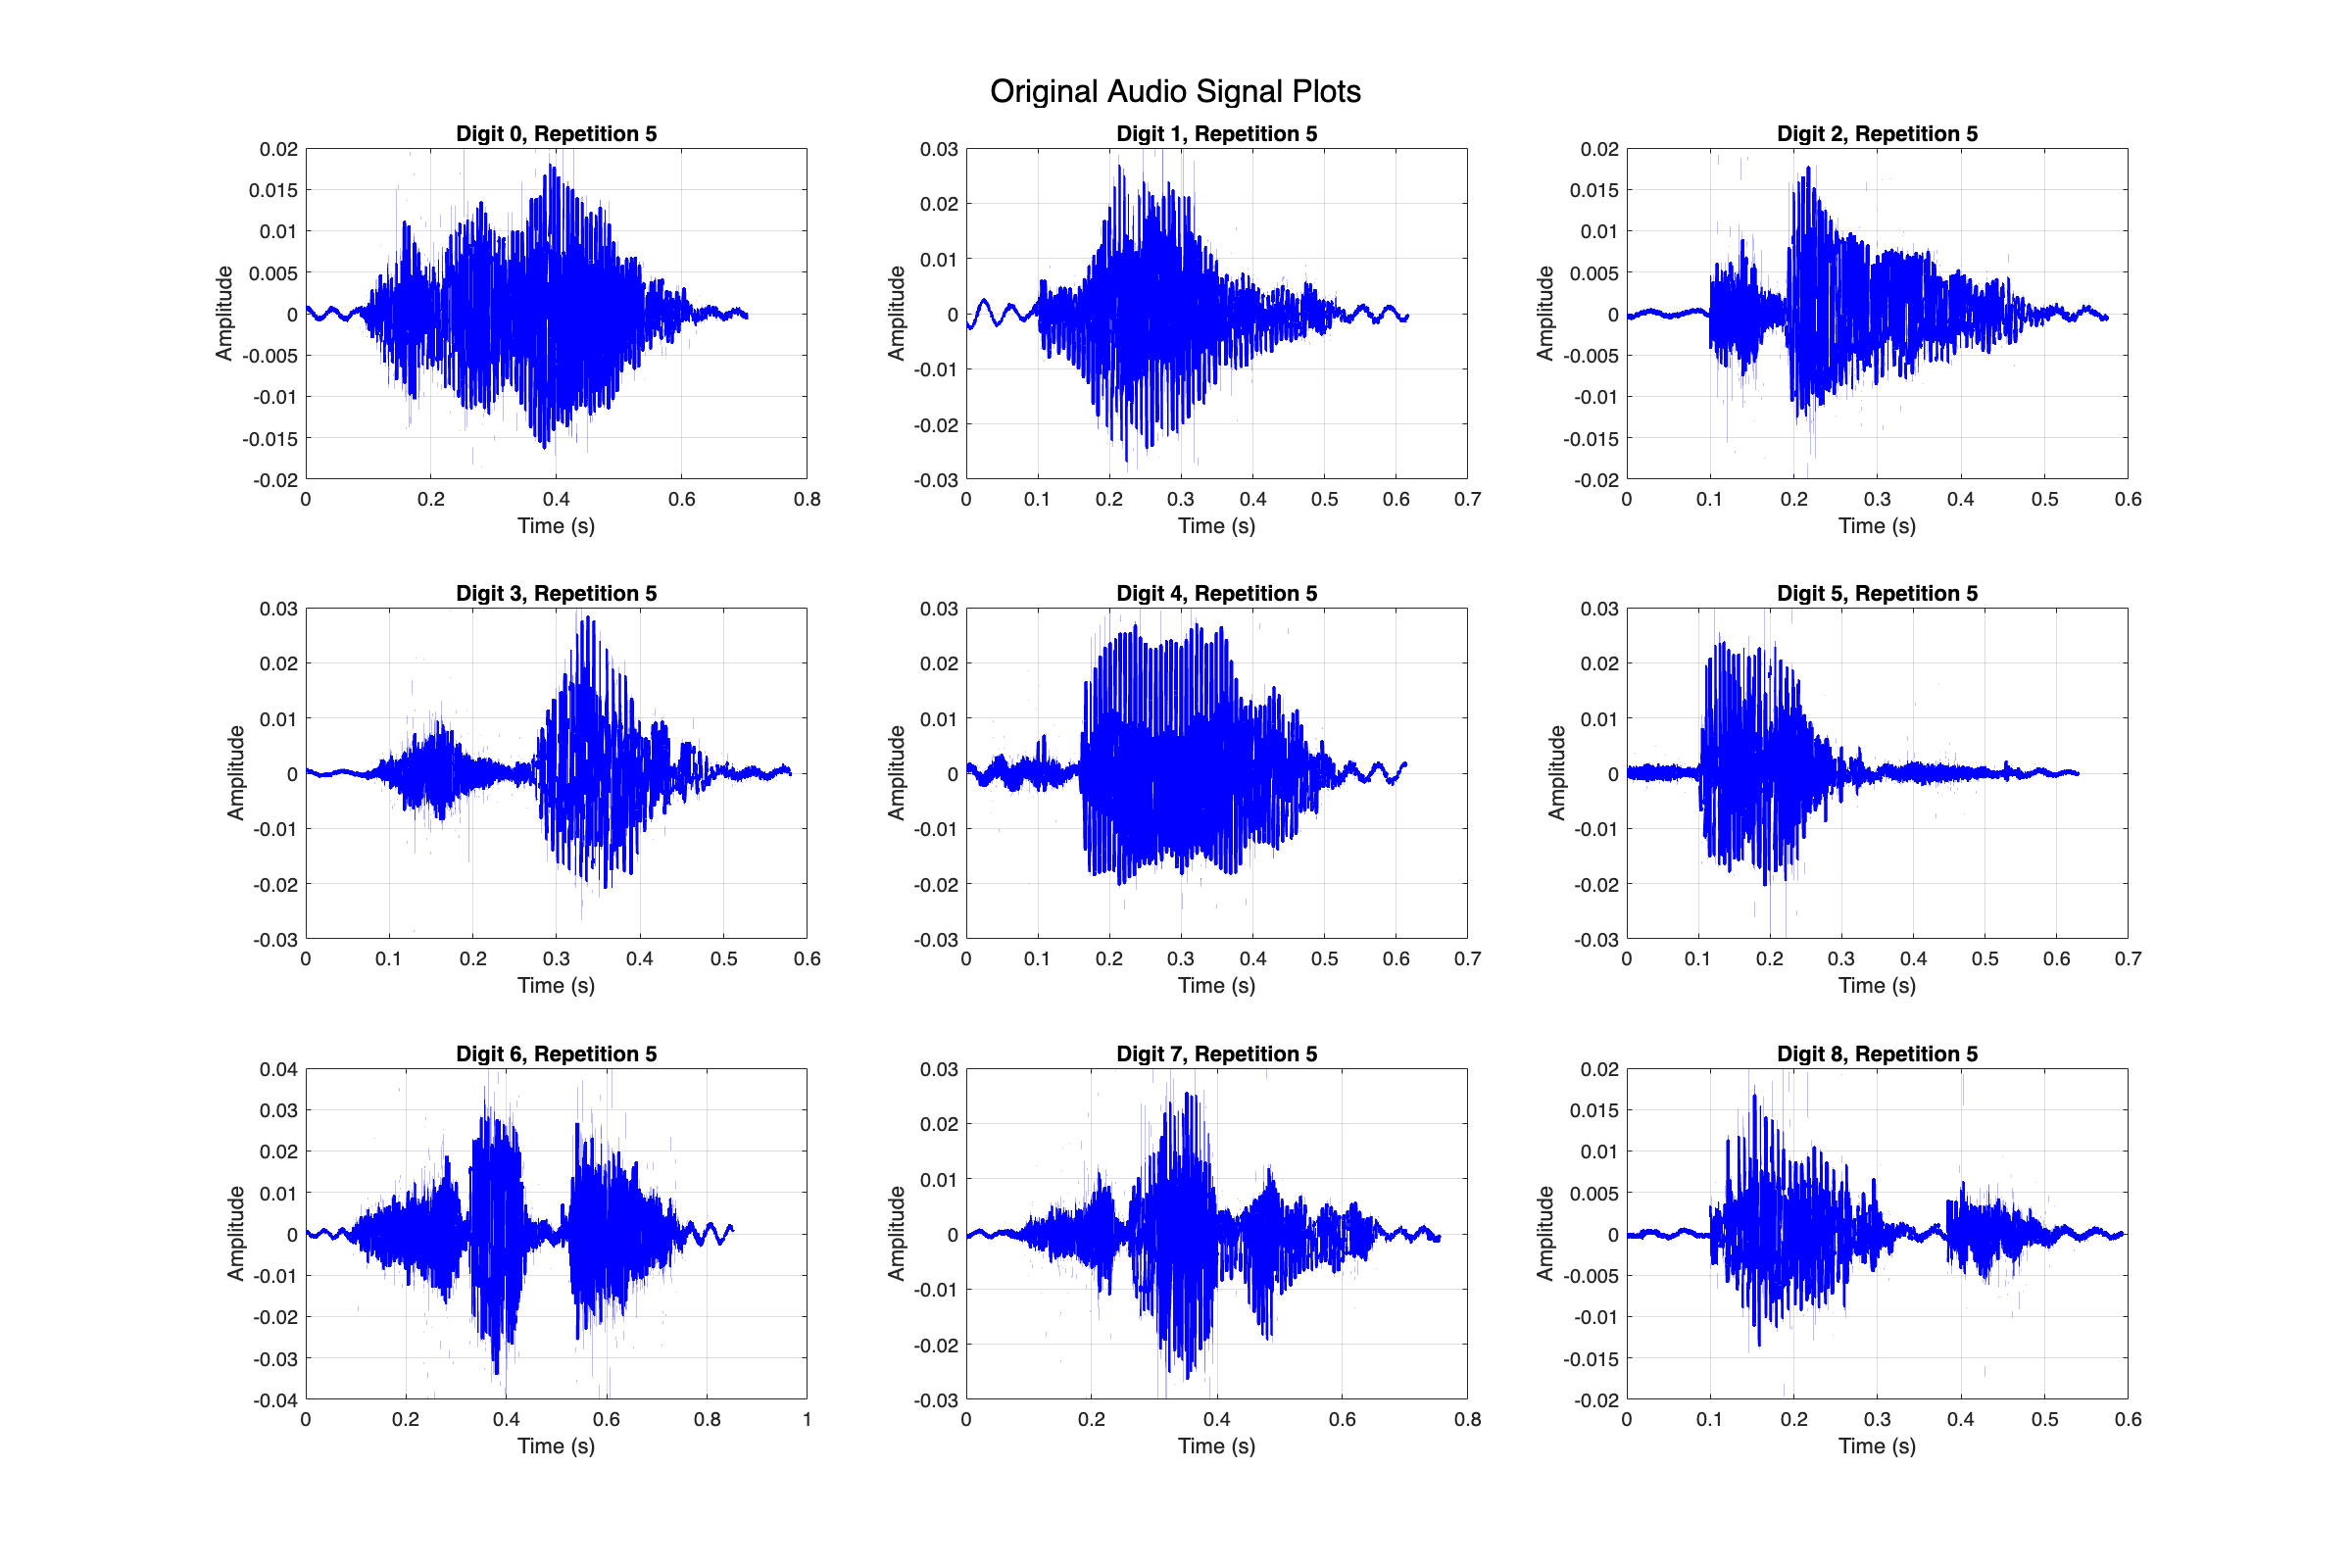

figure('Name', 'OriginalAudioSignalPlots', 'NumberTitle', 'off', 'Position', [100 100 1200 800]);
for currentDigit = 0:8  % ESCOLHER PLOT
    subplot(3, 3, currentDigit + 1);
    signalIndex = find(metadataTable.DigitValue == currentDigit & metadataTable.RepetitionNumber == 5, 1);
    if ~isempty(signalIndex) && ~isempty(metadataTable.RawAudioSignal{signalIndex})
        signalData = metadataTable.RawAudioSignal{signalIndex};
        sampleRate = metadataTable.SamplingRate(signalIndex);
        timeAxis = (0:length(signalData) - 1) / sampleRate;
        plot(timeAxis, signalData, 'b', 'LineWidth', 2); 
        xlabel('Time (s)', 'FontSize', 12);
        ylabel('Amplitude', 'FontSize', 12);
        title(sprintf('Digit %d, Repetition 5', currentDigit), 'FontSize', 14);
        switch currentDigit
            case {0, 2, 8}
                ylim([-0.02 0.02]);
            case {1, 3, 4, 5, 7}
                ylim([-0.03 0.03]);
            case 6
                ylim([-0.04 0.04]);
        end
        grid on;
        set(gca, 'FontSize', 10);
    else
        title(sprintf('Digit %d (not found)', currentDigit), 'FontSize', 14);
    end
end
sgtitle('Original Audio Signal Plots', 'FontSize', 16);

#### EX 4 : Pré-processamento dos ficheiros

####            Objetivo : mesma duração e intervalo de amplitude

% 1) Remover silêncio inicial baseado no energy threshold
% 2) Normalização da amplitude de [-1, 1]

preprocessedAudioSignals = cell(totalRecordings, 1);

for i = 1:totalRecordings
    if ~isempty(metadataTable.RawAudioSignal{i})
        preprocessedSignal = removeInitialSilenceAndNormalize(metadataTable.RawAudioSignal{i}, metadataTable.SamplingRate(i));
    else
        preprocessedSignal = [];
    end
    preprocessedAudioSignals{i} = preprocessedSignal;
end

metadataTable.PreprocessedAudioSignal = preprocessedAudioSignals;

#### EX 5 : Plots de um exemplo dos sinais importados - após pré-processamento

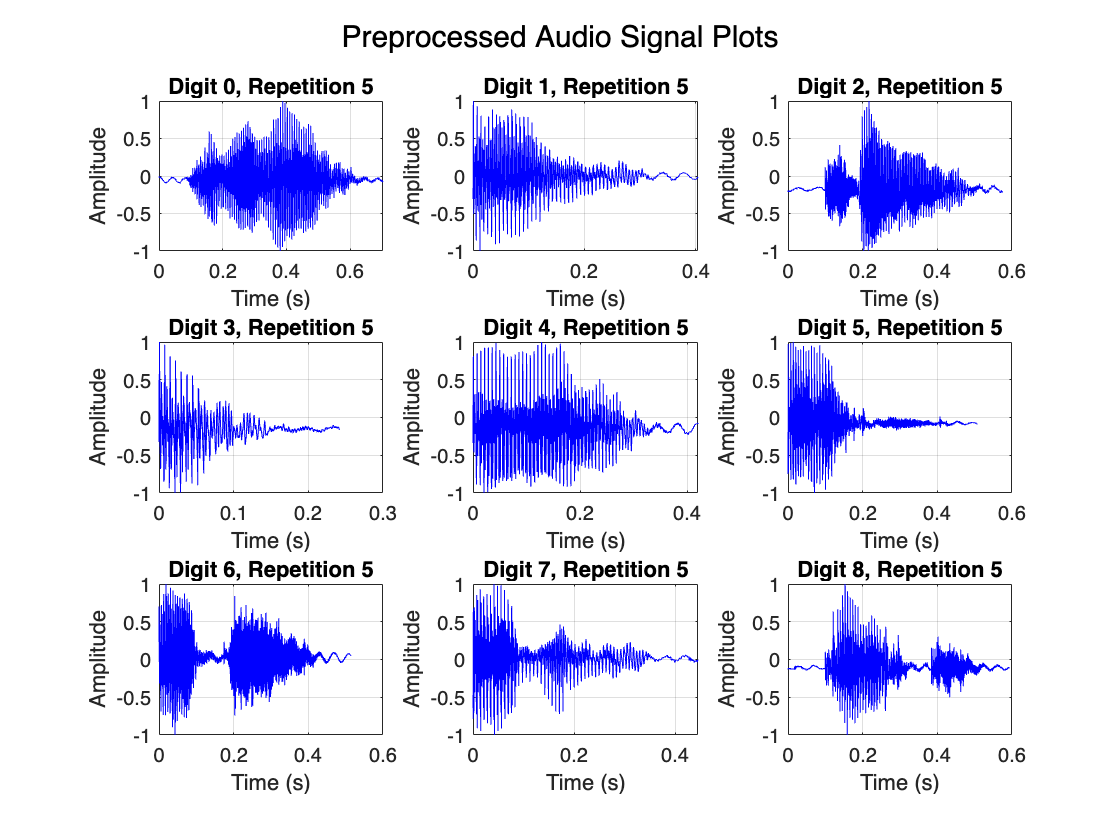

figure('Name', 'PreprocessedAudioSignalPlots', 'NumberTitle', 'off');
for currentDigit = 0:8  % ESCOLHER PLOT
    subplot(3, 3, currentDigit + 1);
    signalIndex = find(metadataTable.DigitValue == currentDigit & metadataTable.RepetitionNumber == 5, 1);
    if ~isempty(signalIndex) && ~isempty(metadataTable.PreprocessedAudioSignal{signalIndex})
        signalData = metadataTable.PreprocessedAudioSignal{signalIndex};
        sampleRate = metadataTable.SamplingRate(signalIndex);
        timeAxis = (0:length(signalData) - 1) / sampleRate;
        plot(timeAxis, signalData, 'b');
        xlabel('Time (s)');
        ylabel('Amplitude');
        title(sprintf('Digit %d, Repetition 5', currentDigit));
        ylim([-1 1]);  % Intervalo de amplitude normalizada 
        grid on;
    else
        title(sprintf('Digit %d (not found)', currentDigit));
    end
end
sgtitle('Preprocessed Audio Signal Plots');

#### EX 7 : Cálculo das features temporais

####         Features : 1) Energia Total, 2) Desvio Padrão, 3) Amplitude Máxima, 4) Taxa de Cruzamento por Zero, 5) Duração (segundos)

numberOfFeatures = 5;
featureMatrix = zeros(totalRecordings, numberOfFeatures);

for i = 1:totalRecordings
    if ~isempty(metadataTable.PreprocessedAudioSignal{i})
        featureValues = extractTemporalFeatures(metadataTable.PreprocessedAudioSignal{i}, metadataTable.SamplingRate(i));
    else
        featureValues = zeros(1, numberOfFeatures);
    end
    featureMatrix(i, :) = featureValues;
end

metadataTable.TotalEnergy      = featureMatrix(:, 1);
metadataTable.StandardDeviation = featureMatrix(:, 2);
metadataTable.MaximumAmplitude  = featureMatrix(:, 3);
metadataTable.ZeroCrossingRate  = featureMatrix(:, 4);
metadataTable.Duration         = featureMatrix(:, 5);

#### EX 8 : Visualização das features

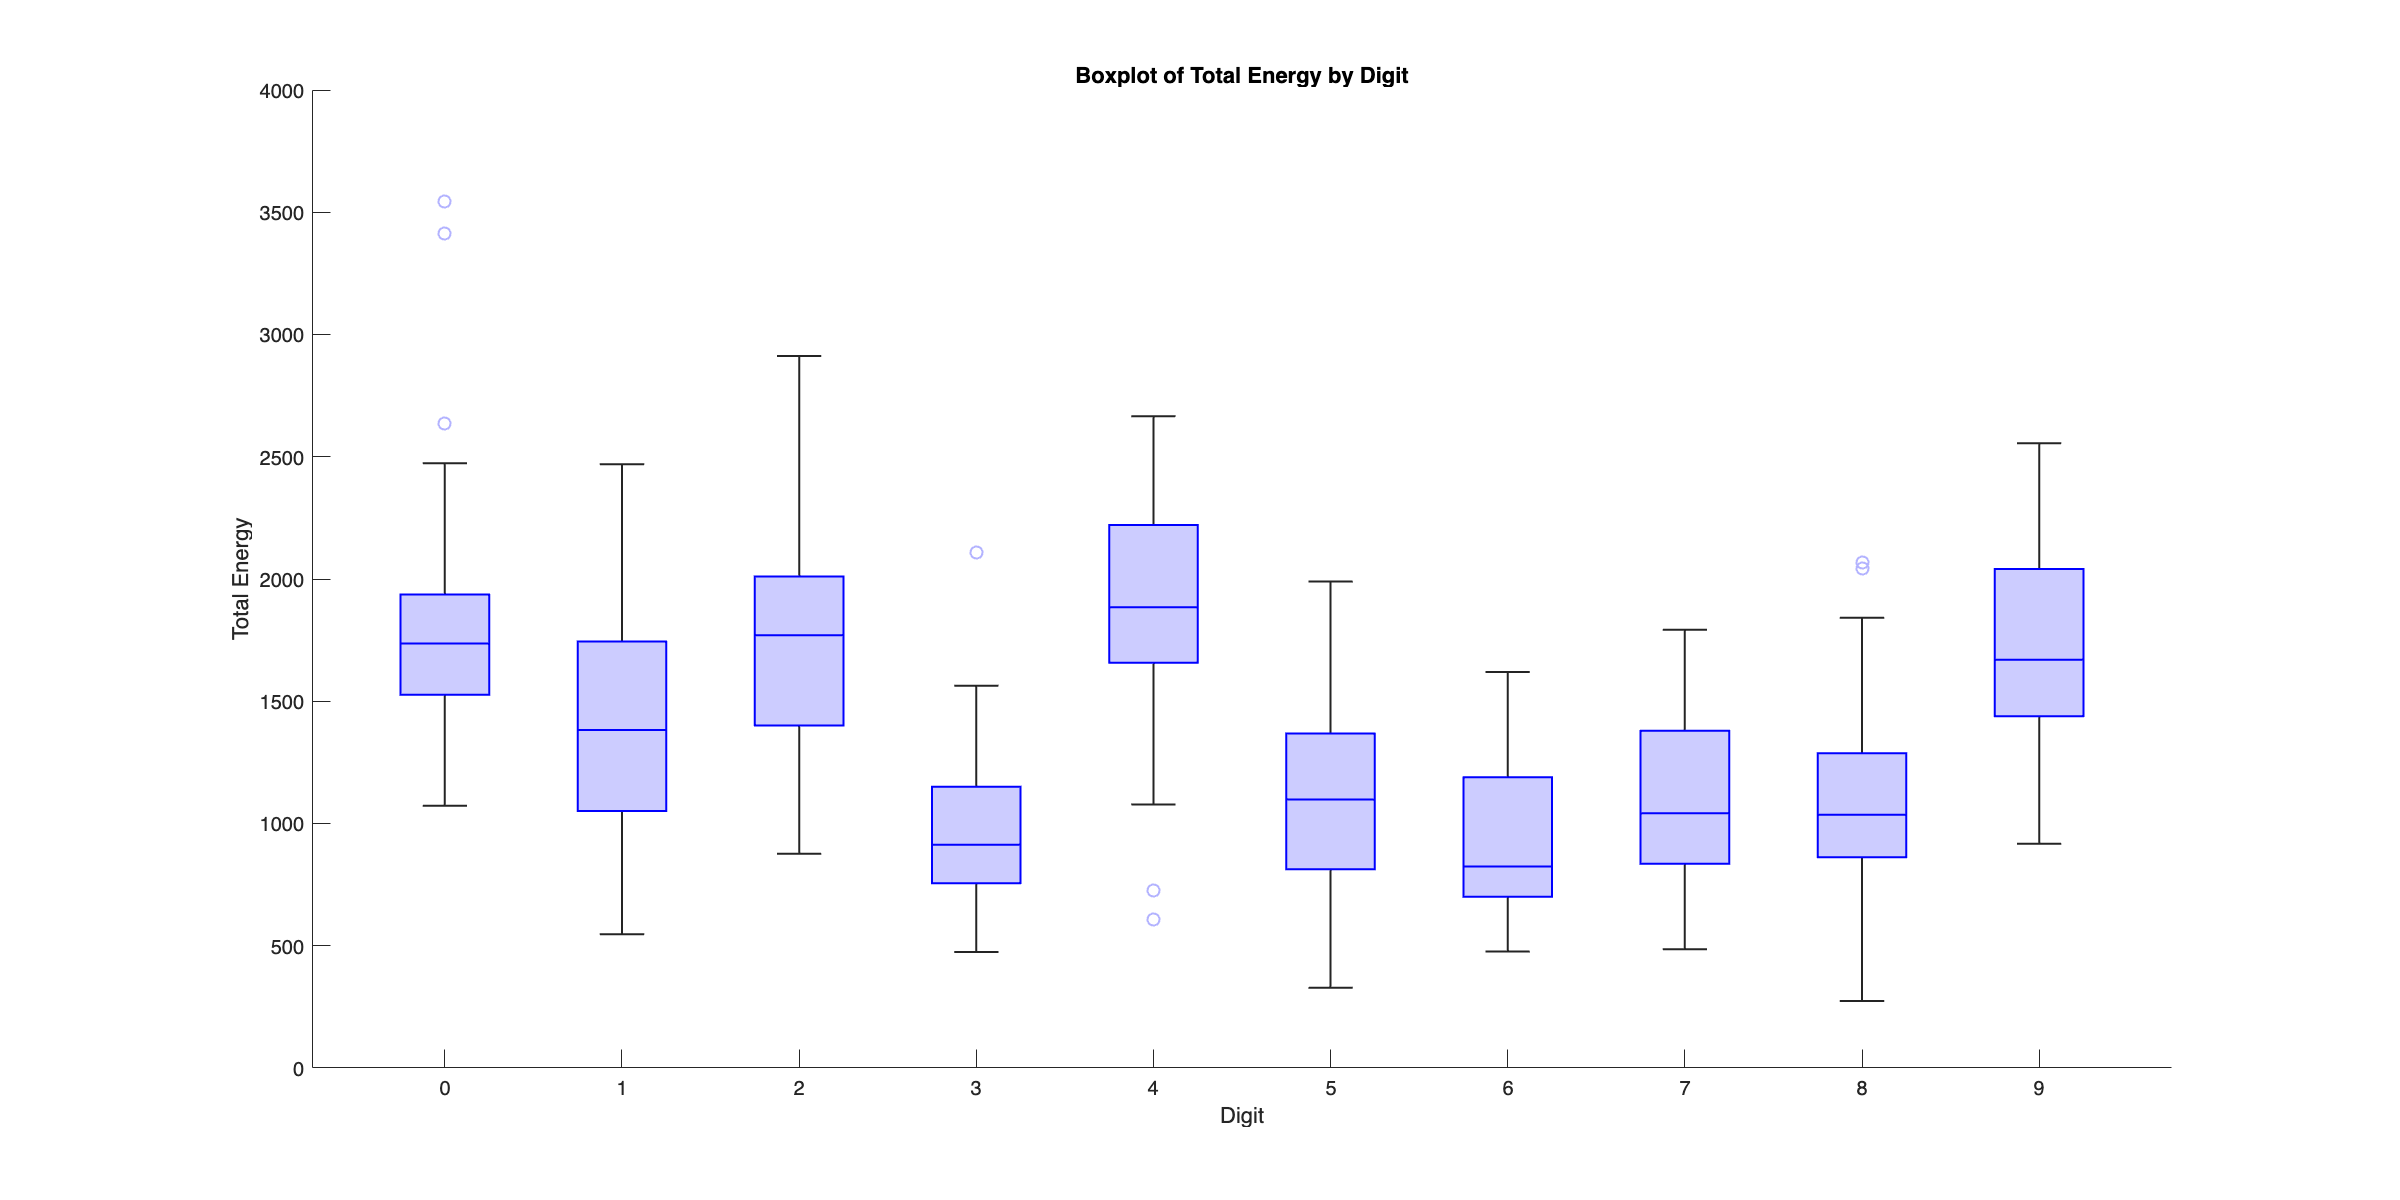


% Boxplot of Total Energy by Digit
figure('Name', 'Boxplot_TotalEnergy', 'NumberTitle', 'off', 'Position', [100, 100, 1200, 600]);
boxchart(categorical(metadataTable.DigitValue), metadataTable.TotalEnergy, 'BoxFaceColor', 'b', 'MarkerColor', [0.7 0.7 1]);
xlabel('Digit');
ylabel('Total Energy');
title('Boxplot of Total Energy by Digit');

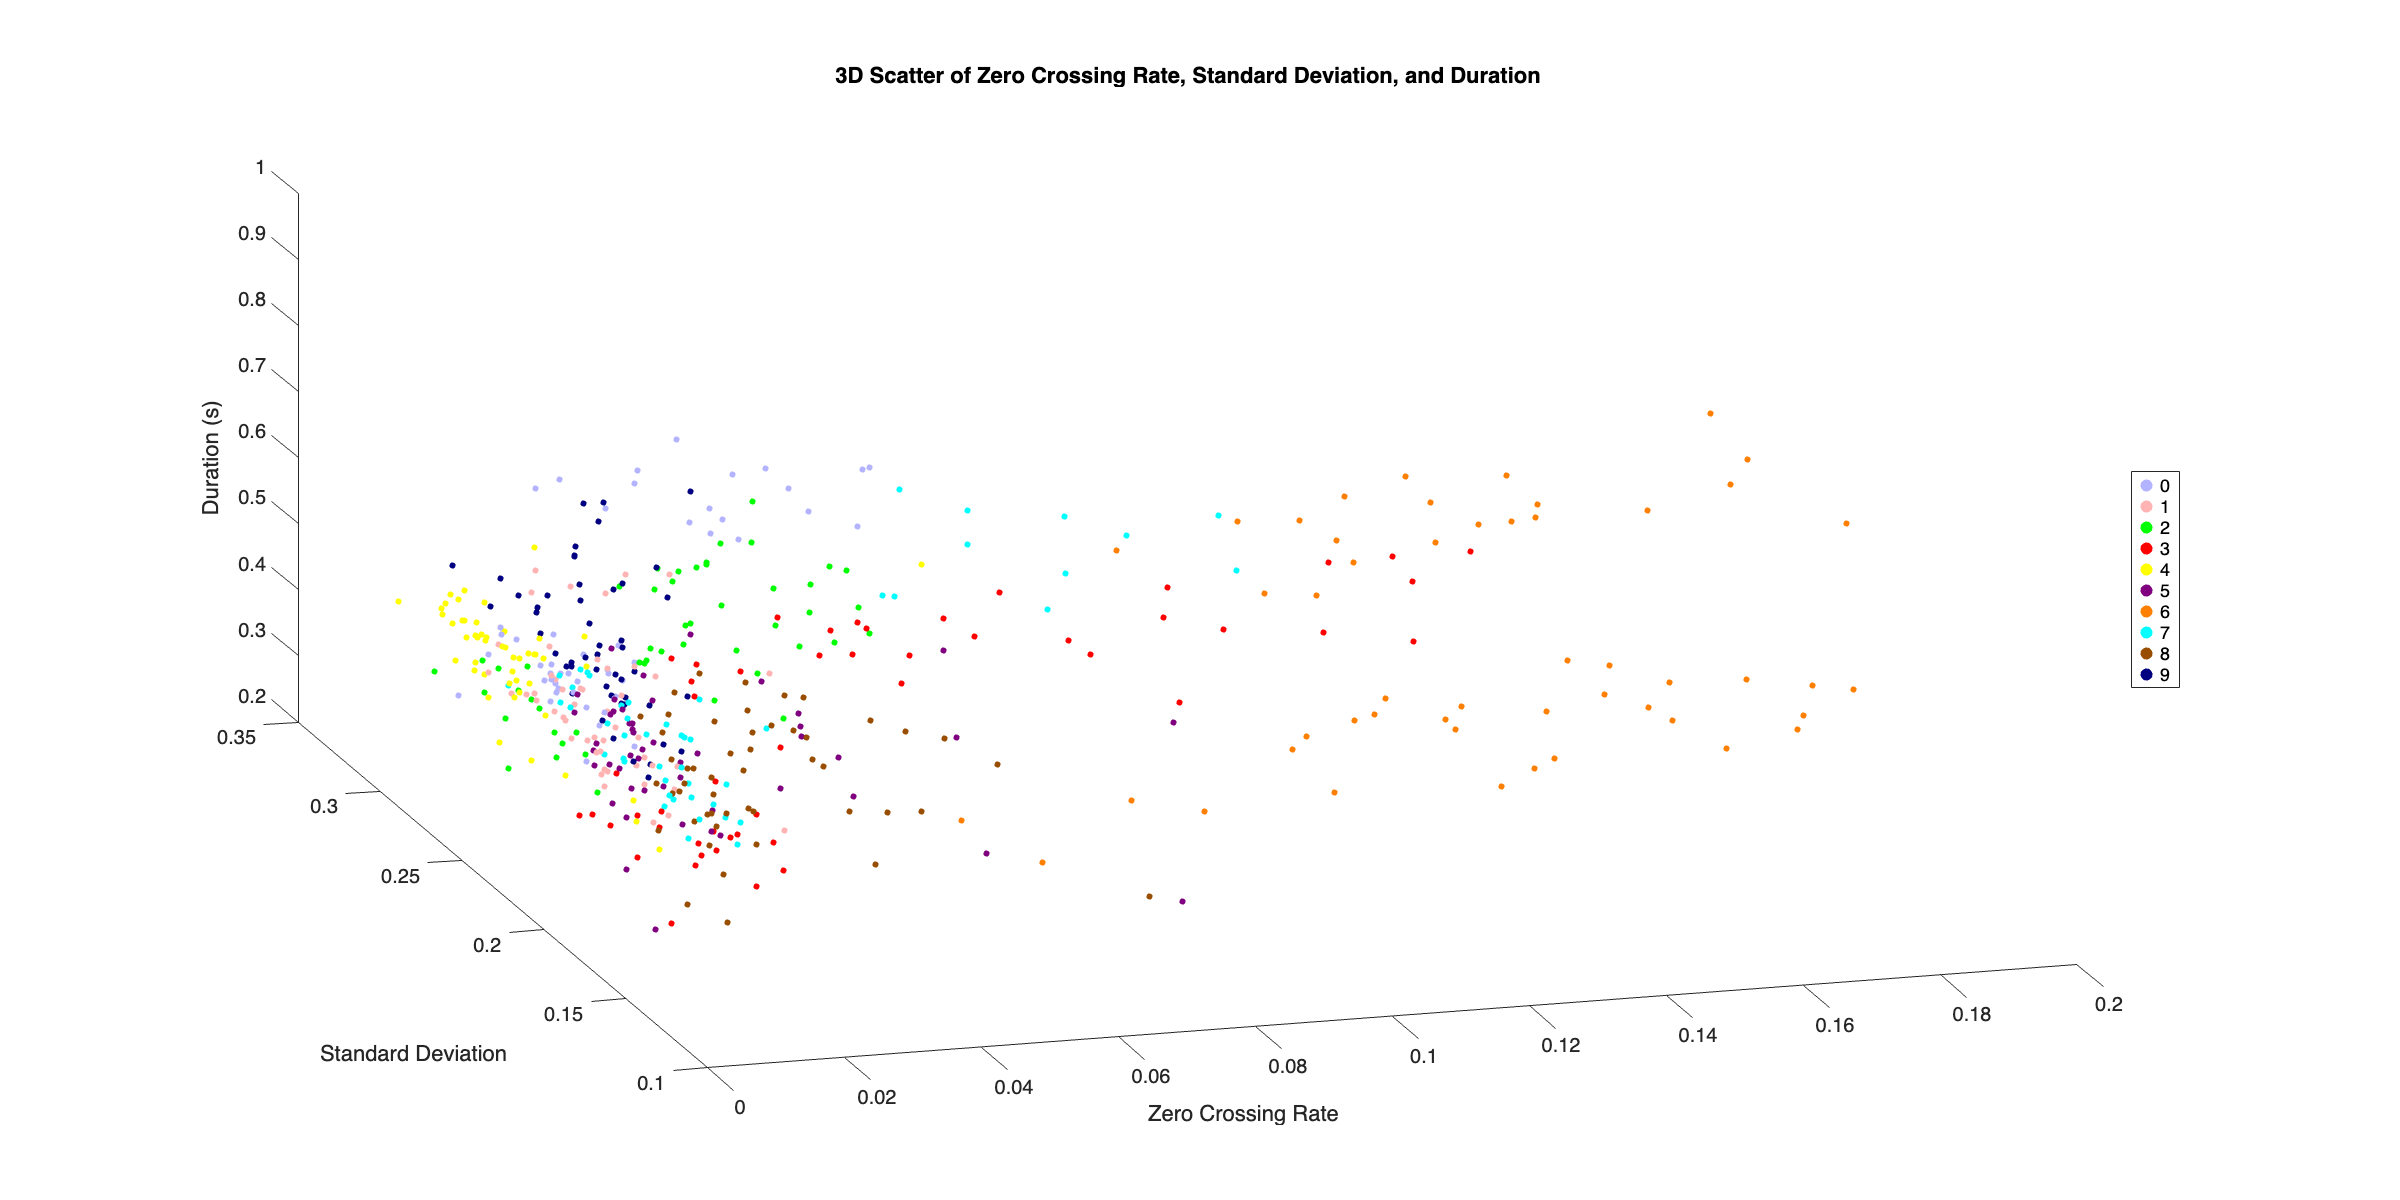


% 3D Scatter Plot of Zero Crossing Rate, Standard Deviation, and Duration
figure('Name', '3DScatter_Features', 'NumberTitle', 'off', 'Position', [100, 100, 1200, 600]);
hold on;
digitColors = [0.7 0.7 1; 1 0.7 0.7; 0 1 0; 1 0 0; 1 1 0; 0.5 0 0.5; 1 0.5 0; 0 1 1; 0.6 0.3 0; 0 0 0.5];
for currentDigit = 0:9
    digitIndices = metadataTable.DigitValue == currentDigit;
    scatter3(metadataTable.ZeroCrossingRate(digitIndices), metadataTable.StandardDeviation(digitIndices), ...
             metadataTable.Duration(digitIndices), 10, digitColors(currentDigit + 1, :), 'filled');
end
hold off;
xlabel('Zero Crossing Rate');
ylabel('Standard Deviation');
zlabel('Duration (s)');
title('3D Scatter of Zero Crossing Rate, Standard Deviation, and Duration');
legend(cellstr(num2str((0:9)')), 'Location', 'eastoutside');

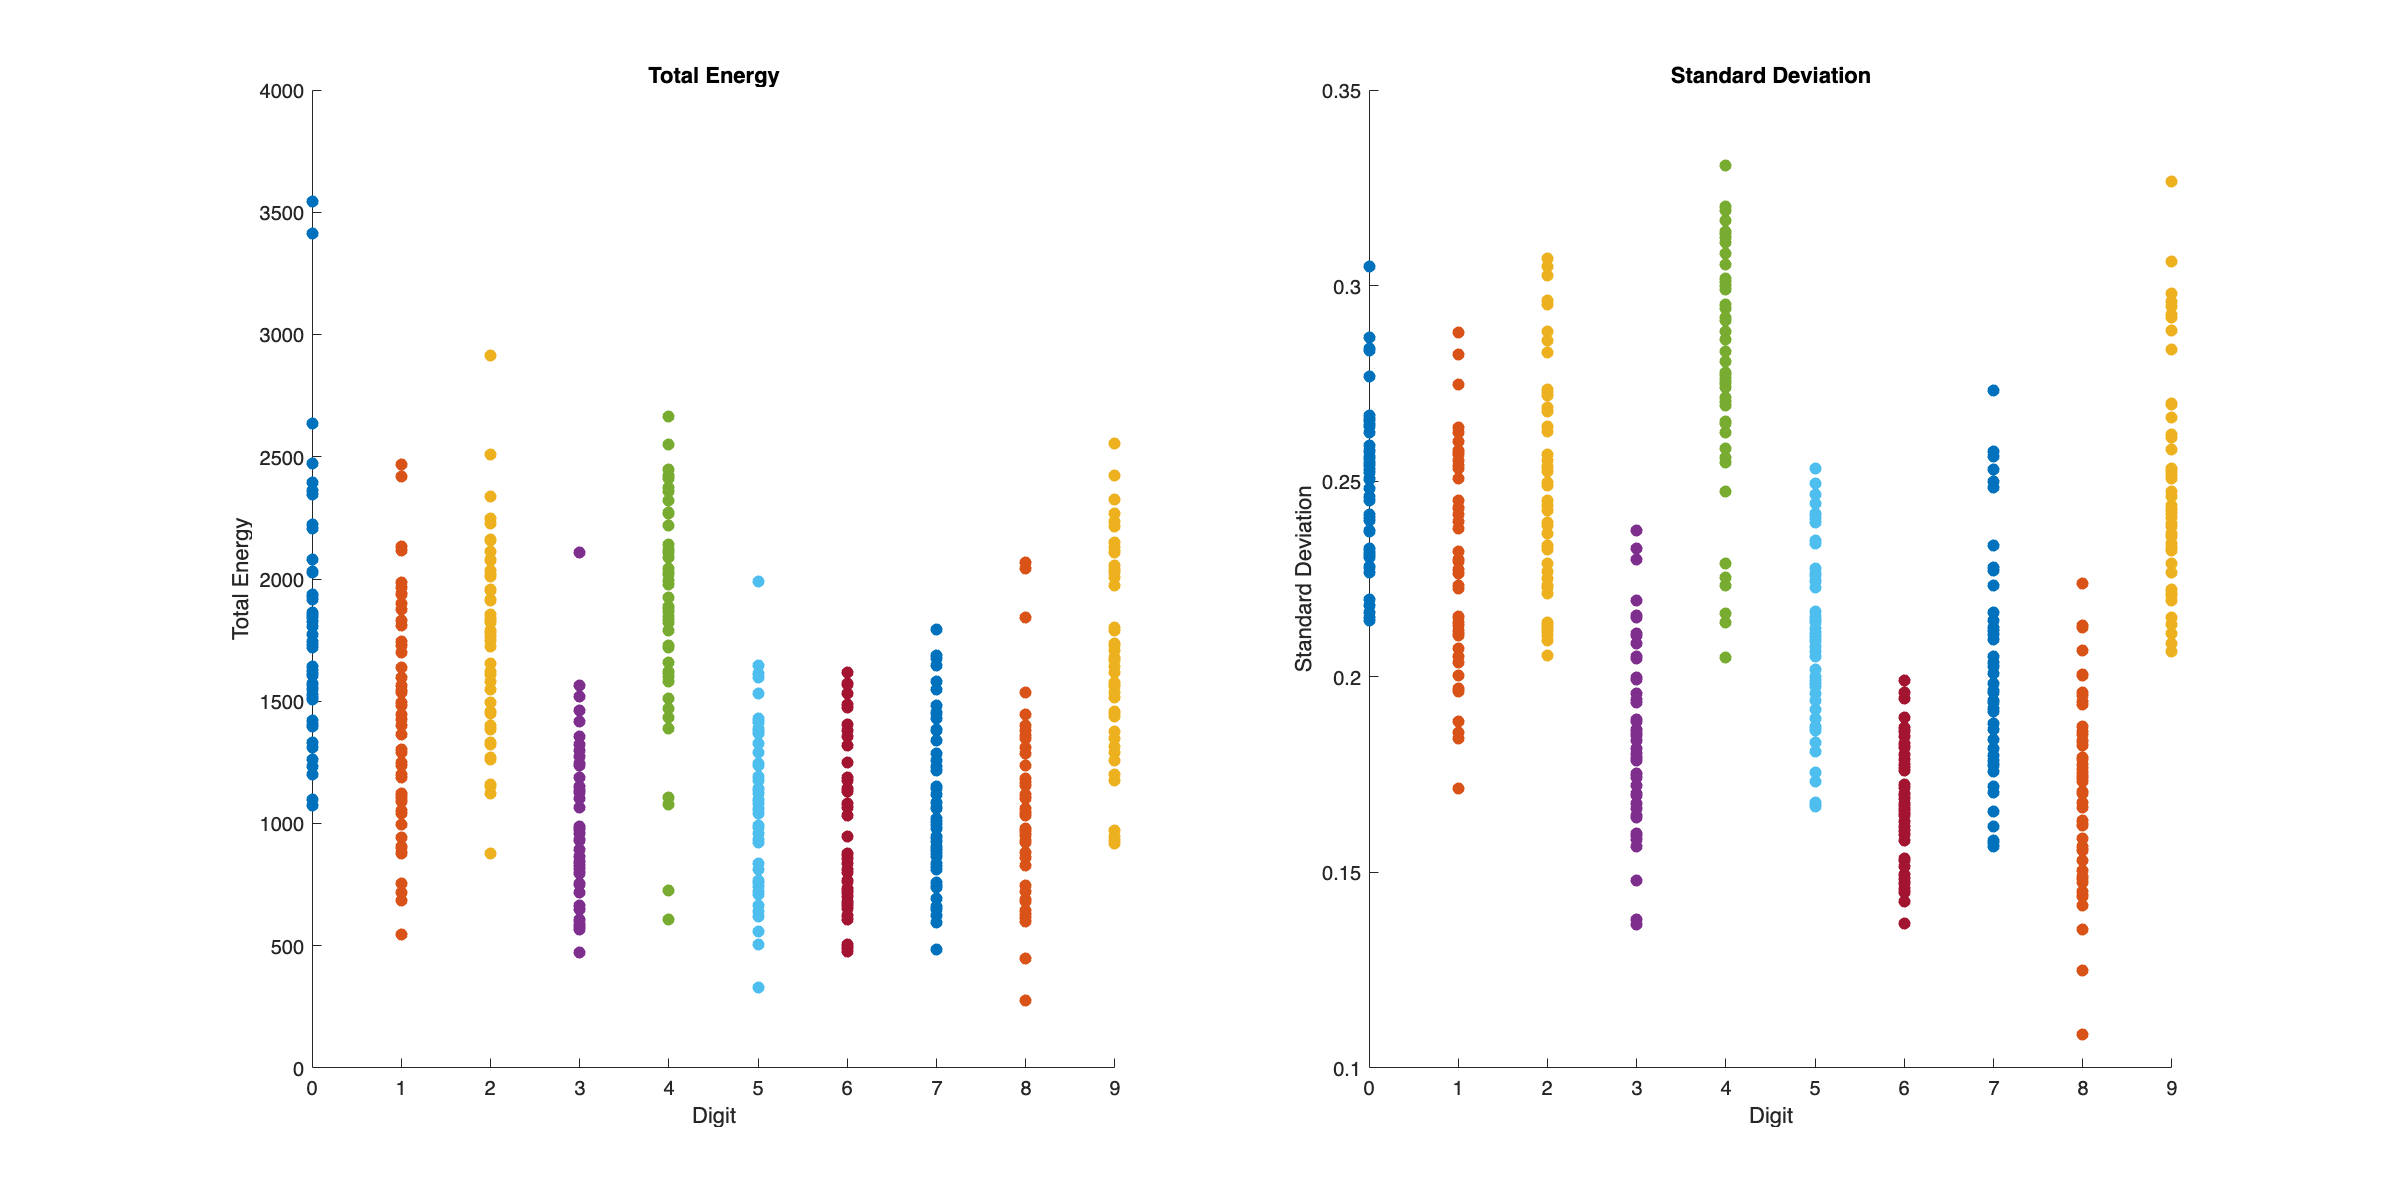

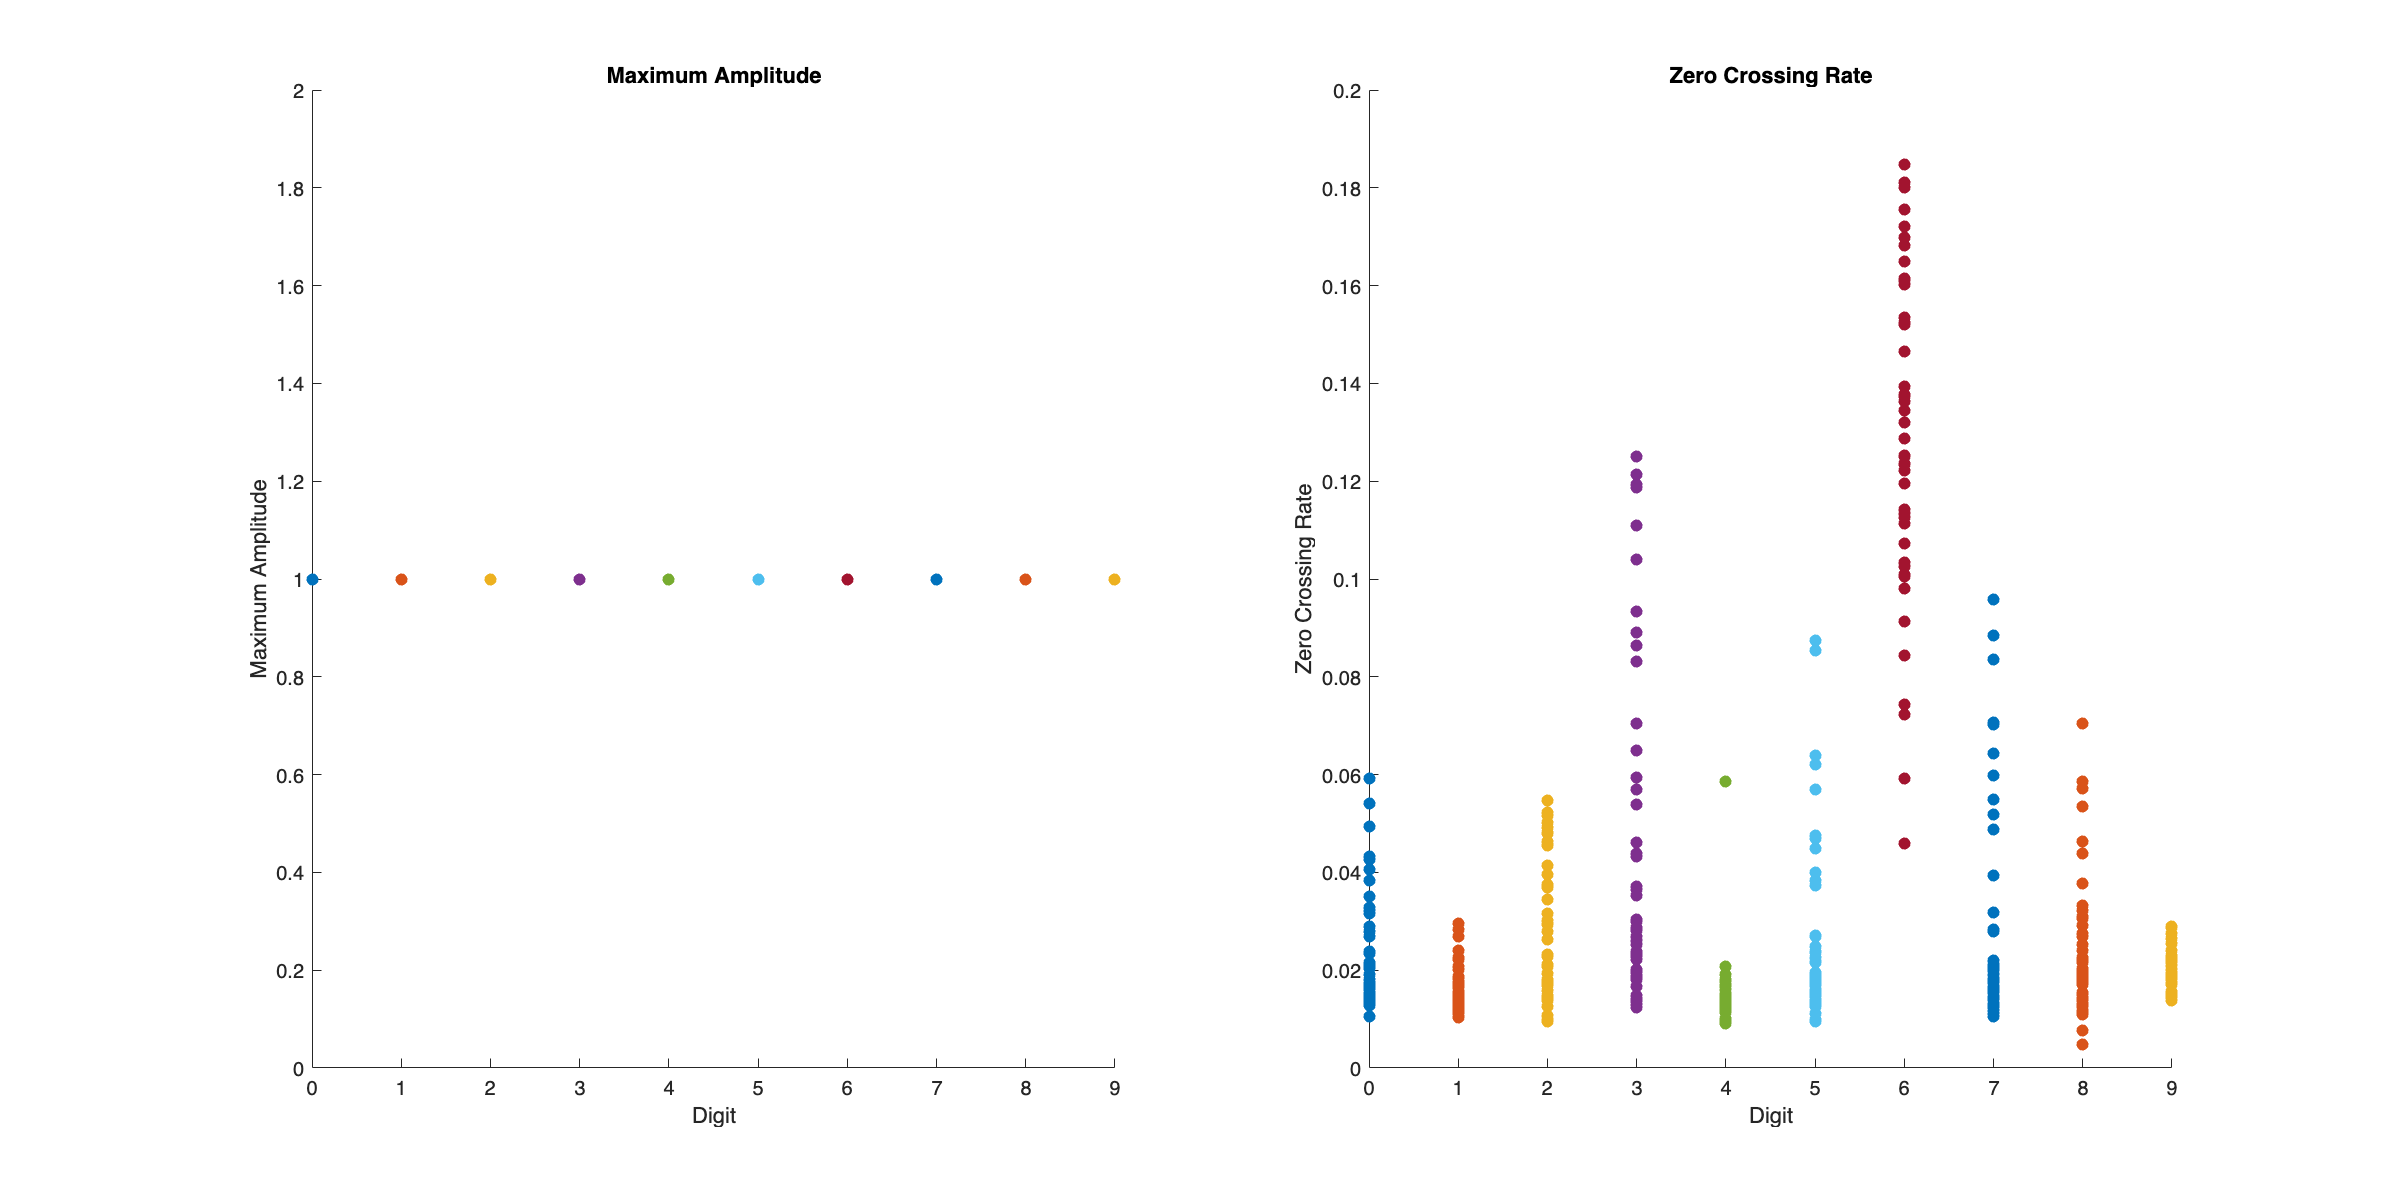

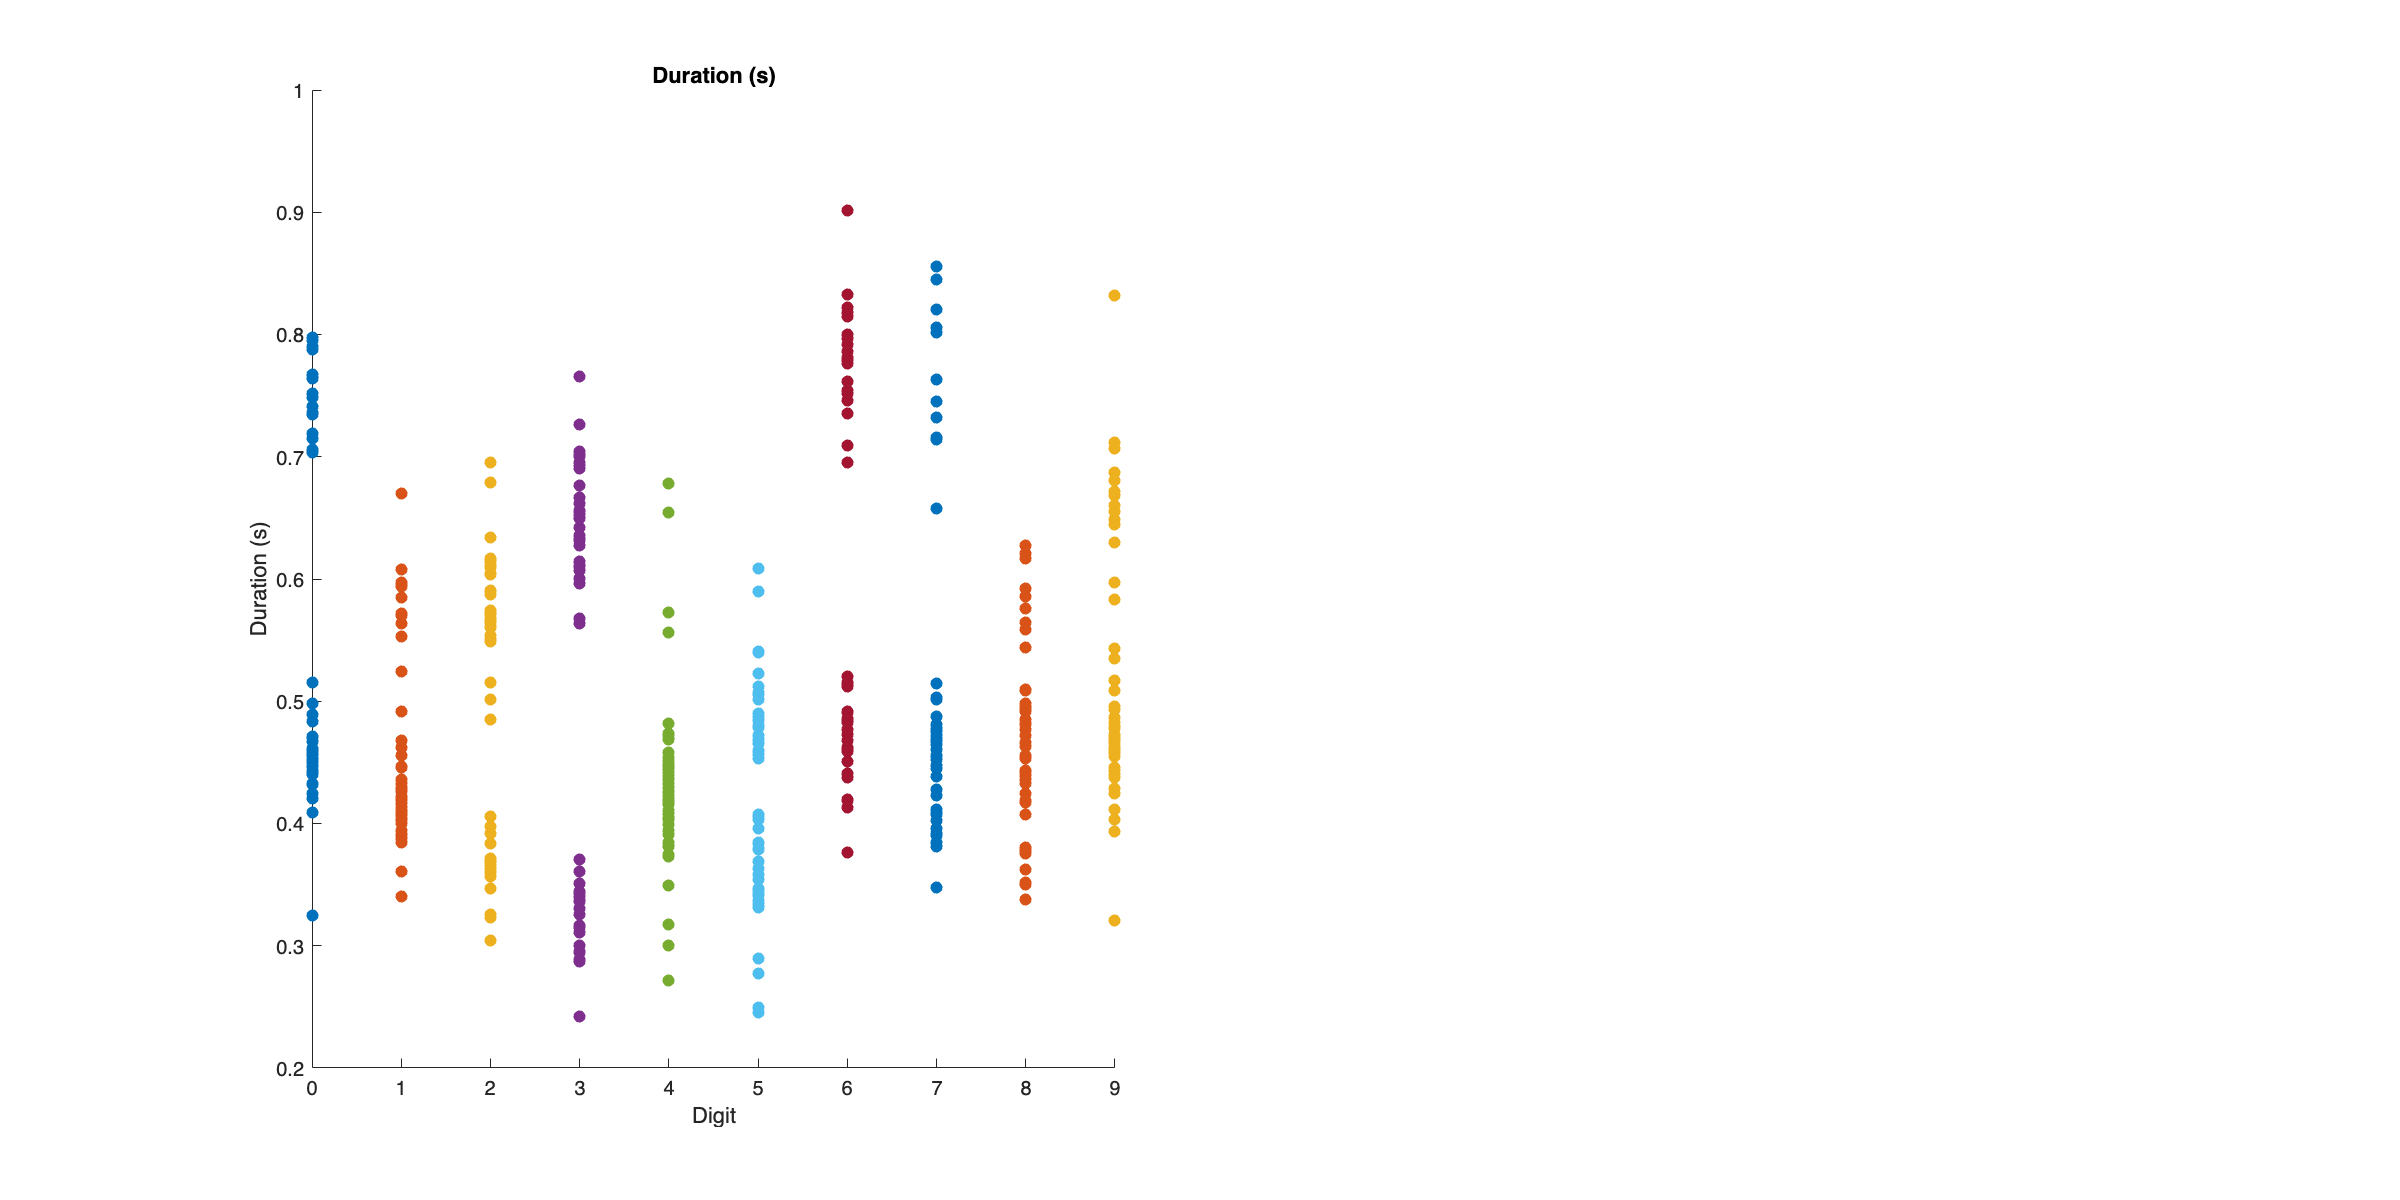


% Scatter Plots of Extracted Features
featureNames = {'Total Energy', 'Standard Deviation', 'Maximum Amplitude', 'Zero Crossing Rate', 'Duration (s)'};
for featureIndex = 1:numberOfFeatures
    if mod(featureIndex, 2) == 1
        figure('Name', ['ScatterPlot_', featureNames{featureIndex}], 'NumberTitle', 'off', 'Position', [100, 100, 1200, 600]);
    end
    subplot(1, 2, mod(featureIndex - 1, 2) + 1);
    hold on;
    for currentDigit = digitNumbers
        digitIndices = (metadataTable.DigitValue == currentDigit);
        scatter(repmat(currentDigit, 1, sum(digitIndices)), featureMatrix(digitIndices, featureIndex), 'filled');
    end
    hold off;
    xlabel('Digit');
    ylabel(featureNames{featureIndex});
    xticks(digitNumbers);
    title(featureNames{featureIndex});
end

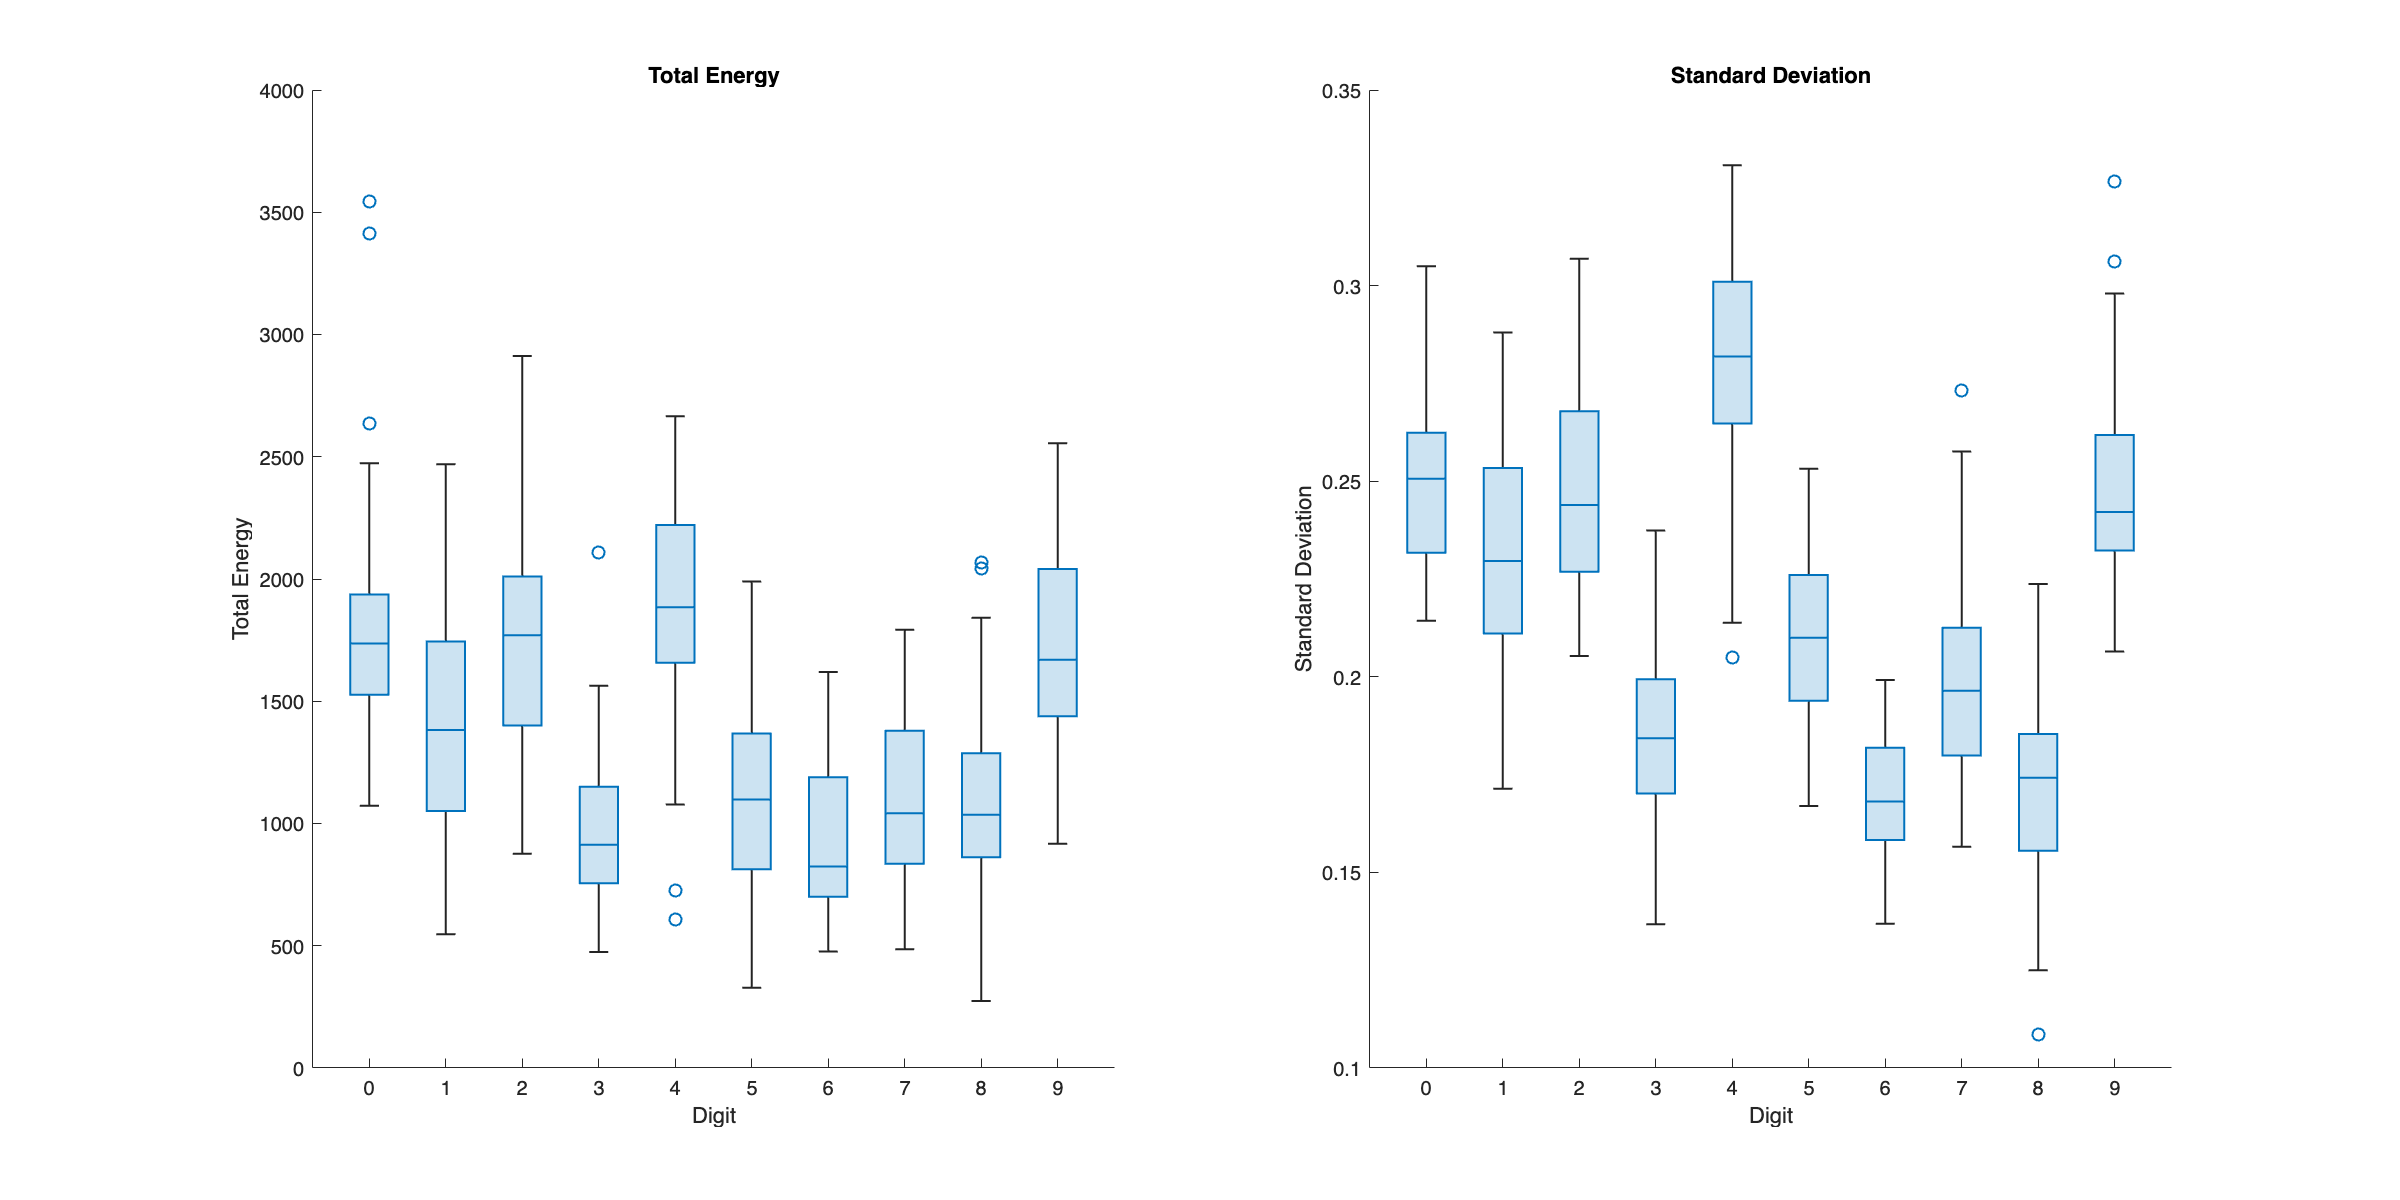

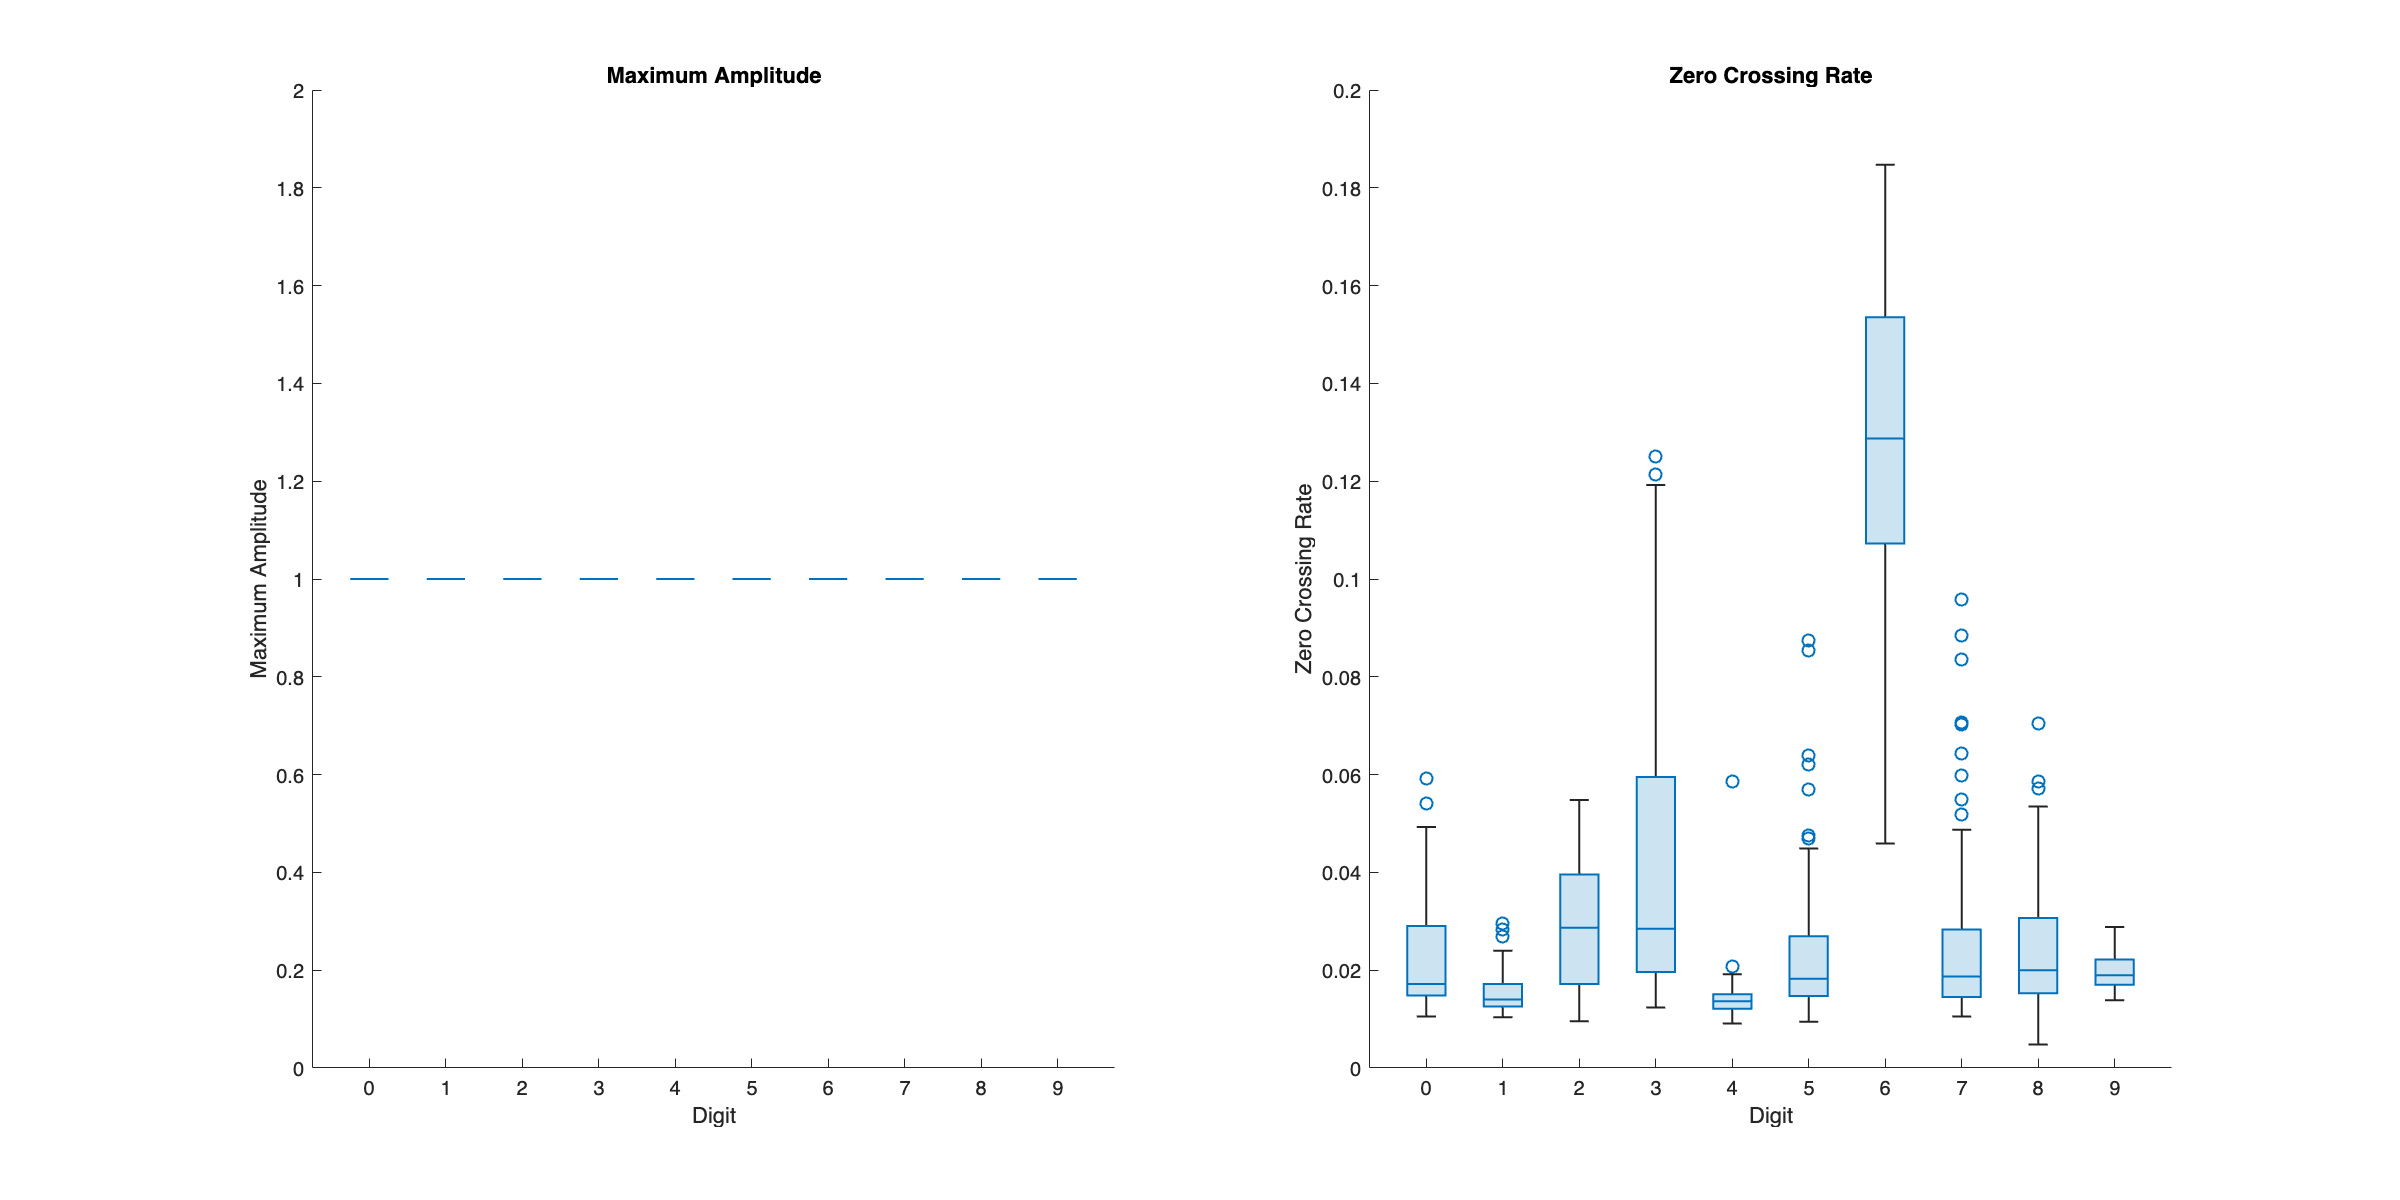

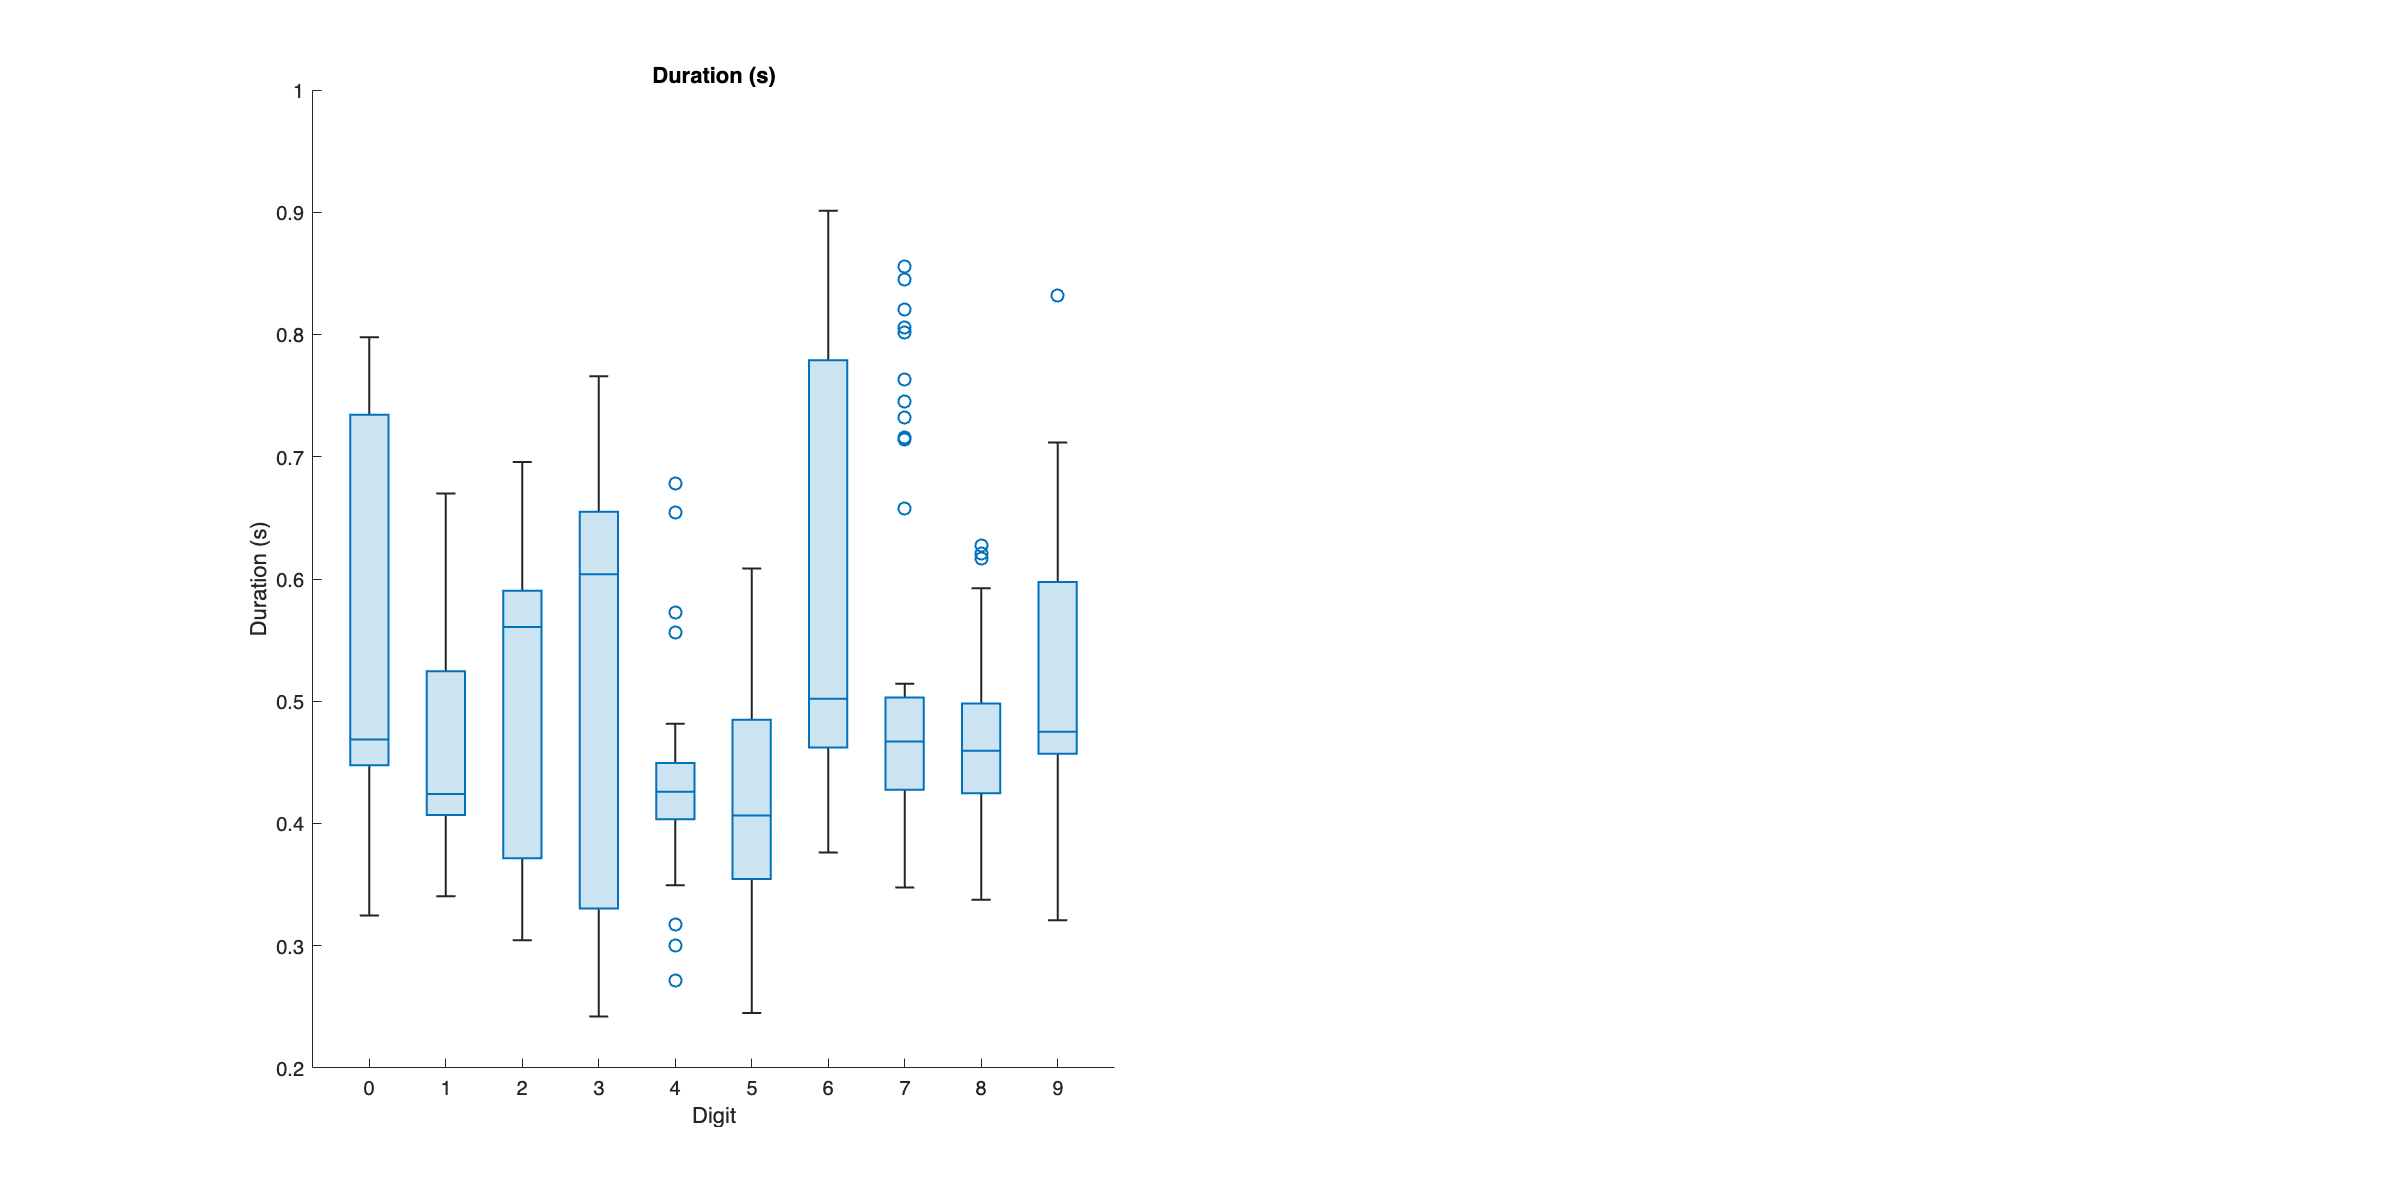


% Boxplots of Extracted Features
for featureIndex = 1:numberOfFeatures
    if mod(featureIndex, 2) == 1
        figure('Name', ['Boxplot_', featureNames{featureIndex}], 'NumberTitle', 'off', 'Position', [100, 100, 1200, 600]);
    end
    subplot(1, 2, mod(featureIndex - 1, 2) + 1);
    boxchart(categorical(metadataTable.DigitValue), featureMatrix(:, featureIndex));
    xlabel('Digit');
    ylabel(featureNames{featureIndex});
    title(featureNames{featureIndex});
end

#### EX 9 : Remoção dos audio signals e guardar a estrutura de dados

metadataTable.RawAudioSignal = [];
metadataTable.PreprocessedAudioSignal = [];
save('finalAudioData.mat', 'metadataTable');

disp('--- End: Audio data structure saved in finalAudioData.mat ---');

--- End: Audio data structure saved in finalAudioData.mat ---


### FUNÇÕES AUXILIARES

function [preprocessedSignal] = removeInitialSilenceAndNormalize(signal, sampleRate)
    frameDurationSec = 0.001;  % Duration of each frame in seconds
    frameSamples = round(frameDurationSec * sampleRate);
    numberOfFrames = floor(length(signal) / frameSamples);
    frameEnergy = calculateFrameEnergy(signal, frameSamples, numberOfFrames);

    energyThreshold = 0.01;  % Threshold to detect signal start
    startFrame = find(frameEnergy > energyThreshold, 1);
    if isempty(startFrame)
        startFrame = 1;
    end
    startSample = (startFrame - 1) * frameSamples + 1;

    preprocessedSignal = signal(startSample:end);

    minValue = min(preprocessedSignal);
    maxValue = max(preprocessedSignal);
    if (maxValue - minValue) < 1e-12  % Avoid division by zero
        preprocessedSignal = zeros(size(preprocessedSignal));
    else
        preprocessedSignal = (preprocessedSignal - minValue) / (maxValue - minValue);  % Intervalo de [0, 1]
        preprocessedSignal = 2 * preprocessedSignal - 1;                              % Intervalo de [-1, 1]
    end
end

function frameEnergy = calculateFrameEnergy(signal, frameSamples, numberOfFrames)
    frameEnergy = zeros(numberOfFrames, 1);
    for frameIndex = 1:numberOfFrames
        frame = signal((frameIndex - 1) * frameSamples + 1 : frameIndex * frameSamples);
        frameEnergy(frameIndex) = sum(frame .^ 2);
    end
end

function featureValues = extractTemporalFeatures(signal, sampleRate)
    featureValues = zeros(1, 5);
    featureValues(1) = sum(signal .^ 2);         % Total Energy
    featureValues(2) = std(signal);              % Standard Deviation
    featureValues(3) = max(abs(signal));         % Maximum Amplitude
    featureValues(4) = calculateZeroCrossingRate(signal);  % Zero Crossing Rate
    featureValues(5) = length(signal) / sampleRate;       % Duration in seconds
end

function zeroCrossingRate = calculateZeroCrossingRate(signal)
    signalSign = sign(signal);
    signDifference = diff(signalSign);
    zeroCrossingRate = sum(signDifference ~= 0) / (length(signal) - 1);
end
